# Impairments

## Signal

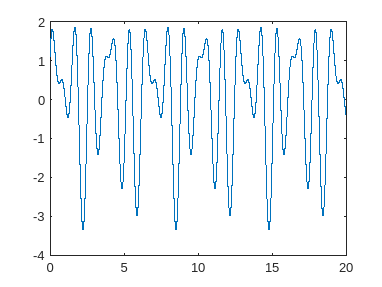

Fs = 1e3;
delta_t = 1/Fs;
time_duration = 20;
t = 0:delta_t:time_duration;

signal_tx = 0.8*sin(2*t) + 1.5*sin(5*t) + 1.1 * sin(7*t+pi/2);
plot(t, signal_tx);

## DC offset

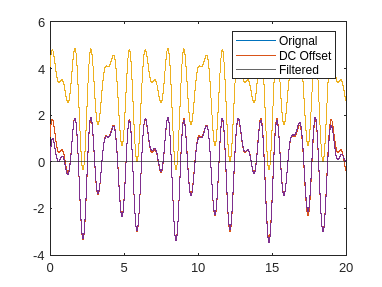



hold on
plot(t, signal_tx);
yline(0);

dc_offset = 3;

signal_rx = dc_offset + signal_tx;
plot(t, signal_rx);
signal_rx_fixed = highpass(signal_rx, 0.2, Fs);
plot(t, signal_rx_fixed);

legend('Orignal', 'DC Offset', 'Filtered')

hold off

## Frequancy shift